Ts = 100;
N0 = 1;
rng('default')

n = randn(1, Ts*10) * sqrt(90);

rv = rand(1, 10);

% rv = [0.2 0.4 0.6 0.8 1]
bits = (rv < 0.25) * 1;
bits = bits + ((rv >= 0.25) & (rv < 0.5)) * 3;
bits = bits + ((rv >= 0.5) & (rv < 0.75)) * -1;
bits = bits + (rv >= 0.75) * -3

bits =     -3     1     3     1    -1     1     1    -1     3    -1



wave = repelem(bits, 1, Ts);

waven = wave + n

waven =     2.1008   14.3978  -24.4293    5.1793    0.0241  -15.4058   -7.1134    0.2504   30.9477   23.2732  -15.8062   25.7918    3.8818   -3.5982    3.7806   -4.9445   -4.1777   11.1325   10.3673   10.4447    3.3704  -14.4552    3.8043   12.4658    1.6381    6.8160    3.8958   -5.8787   -0.2121  -10.4688    5.4281  -13.8821  -13.1402  -10.6796  -30.9319   10.6457    0.0850  -10.1619    9.9998  -19.2369   -3.9700   -5.2906    0.0283   -0.0320  -11.2050   -3.2851   -4.5642    2.9550    7.3716    7.5235


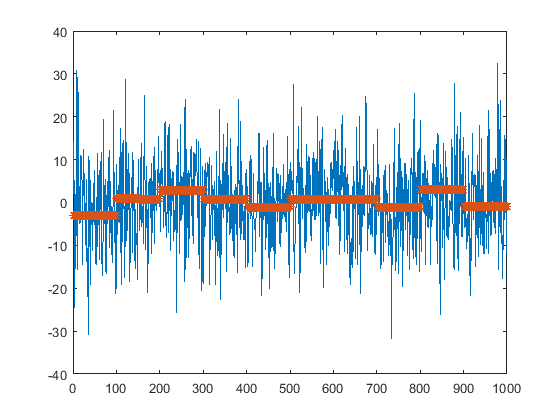

plot(1:Ts*10, waven, 1:Ts*10, wave, '*');


sb = ones(1, Ts);

d = 1;

si = d * sb;

y = conv(wave, si)

y =     -3    -6    -9   -12   -15   -18   -21   -24   -27   -30   -33   -36   -39   -42   -45   -48   -51   -54   -57   -60   -63   -66   -69   -72   -75   -78   -81   -84   -87   -90   -93   -96   -99  -102  -105  -108  -111  -114  -117  -120  -123  -126  -129  -132  -135  -138  -141  -144  -147  -150


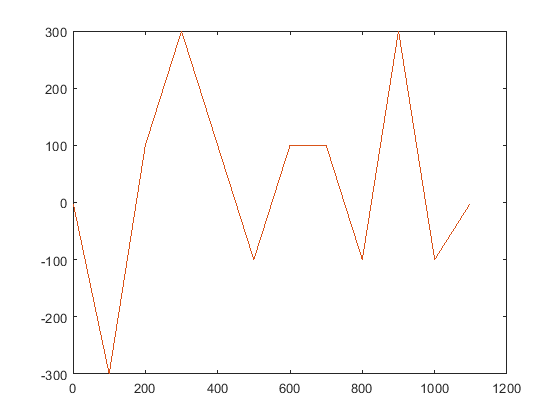

plot(1:Ts*11-1, y, 1:Ts*11-1, y)


% s0 = 1 * si + n;
% 
% s1 = 3 * si+ n;
% 
% s2 = -1 * si + n;
% 
% s3 = -3 * si + n;
% 
% sc = si;
% 
% y0 = conv(sc, s0);
% y1 = conv(sc, s1);
% y2 = conv(sc, s2);
% y3 = conv(sc, s3);
% plot(1:Ts*2-1, y0,1:Ts*2-1, y1,1:Ts*2-1, y2,1:Ts*2-1, y3)
% yk0 = y0(Ts)
% yk1 = y1(Ts)
% yk2 = y2(Ts)
% yk3 = y3(Ts)